# **FIT3081 Lab Task**

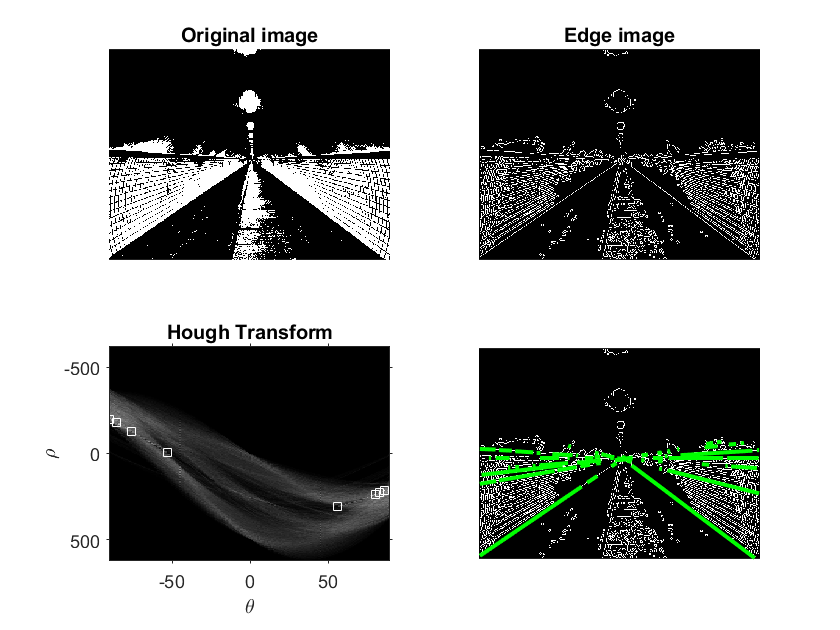

file1 = imread('vanishing-00.jpg');
line_detection(file1,8);

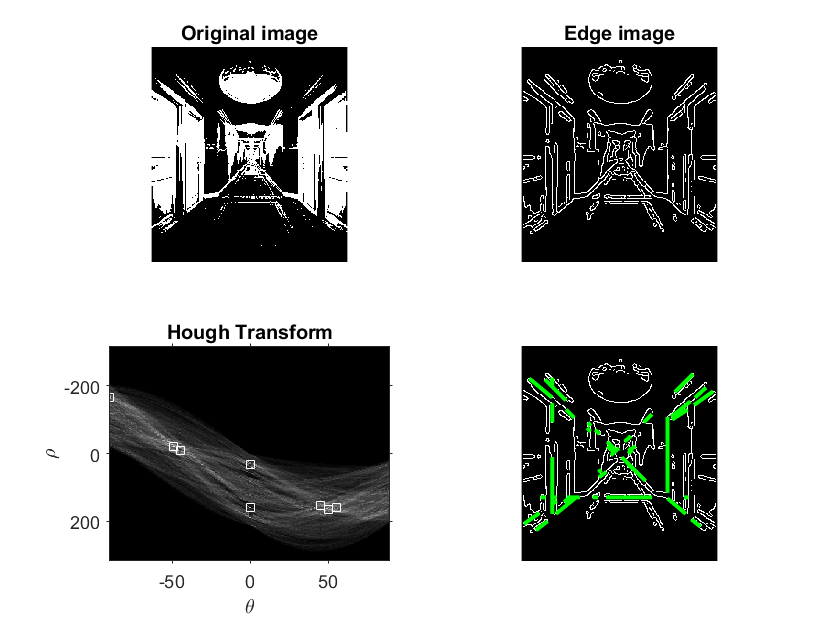


file2 = imread('vanishing-01.jpg');
line_detection(file2,8);

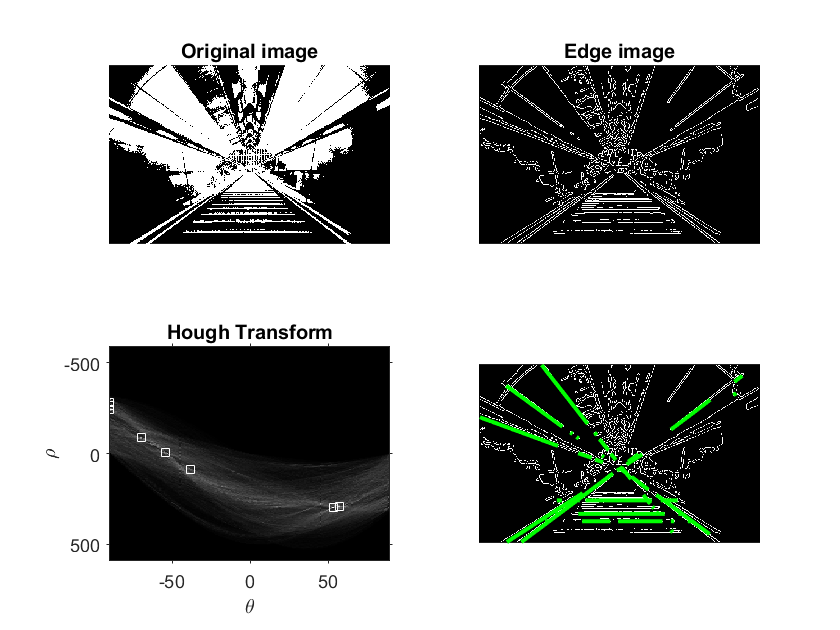


file3 = imread('vanishing-02.jpg');
line_detection(file3,8);

The code below was taken from Week 4's lab(slide 25-27)

function o = line_detection(I,hough_peak)
    %Edge detection
    % Edge detection using Canny edge detector
    BW=rgb2gray(I);
    BW=imbinarize(BW);
    figure,subplot(2,2,1), imshow(BW),title('Original image');
    BW = edge(BW,'canny');
    subplot(2,2,2), imshow(BW),title('Edge image');
    
    
    %Hough transform:
    % Find Theta (T) and Rho (R) values and plot them for visualisation
    [H,T,R] = hough(BW);
    subplot(2,2,3), imshow(H,[],'XData',T,'YData',R),title('Hough Transform');
    xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
    
    %Find Hough peaks.
    P = houghpeaks(H,hough_peak);
    x = T(P(:,2)); y = R(P(:,1));
    plot(x,y,'s','color','white');% Plot them in white colour
    
    %Line detection
    % Draw the detected straight lines
    lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',4);
    subplot(2,2,4), imshow(BW), hold on
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    end
end